# **DigitalTwin & Automation**

## **TEAM PROJECT**

### **Battery RUL Prognosis using NASA Battery Dataset**

Name:         Park Jeong Woo

                    Yu Jin Su

                    Hong Se Hyun

## **Outline**

**    1.    Problem & Data Description**

**    2.    Data Exporation & Pre-processing**

**    3.    Feature Extraction**

**    4.    Post-processing & Feature Selection with Monotonicity**

**    5.    Dimention Reduction with PCA**

**    6.    RUL**

**    7.    Discussion & Conclusion**

**    8.    Reference**

# **1.    Problem & Data Description**

## Introduction

With the recent increase in the use of lithium-ion batteries, predicting the remaining life of the batteries has become an important topic.

In this project, we predict the remaining life of the battery based on the battery data set provided by NASA.

In summary, It is about predicting the remaining useful life of the Lithium Ion battery on constant current discharge.

## **Dataset**

Download NASA Lithium ION Battery dataset : [Download here](https://ti.arc.nasa.gov/tech/dash/groups/pcoe/prognostic-data-repository/)

                 └ "Battery Data Set", NASA Ames Prognostics Data Repository

### Data Description:

A set of four Li-ion batteries (# 5, 6, 7 and 18) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at a constant current (CC) level of 2A until the battery voltage fell to 2.7V, 2.7V, 2.2V and 2.7V for batteries 5 6 7 and 18 respectively. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).

### Data Parameter Description

#### Data Structure:

cycle: top level structure array containing the charge, discharge and impedance operations

type: operation type, can be charge, discharge or impedance

ambient_temperature: ambient temperature (degree C)

time: the date and time of the start of the cycle, in MATLAB date vector format

data: data structure containing the measurements

#### for charge the fields are:

Voltage_measured: Battery terminal voltage (Volts)

Current_measured: Battery output current (Amps)

Temperature_measured: Battery temperature (degree C)

Current_charge: Current measured at charger (Amps)

Voltage_charge: Voltage measured at charger (Volts)

Time: Time vector for the cycle (secs)

#### for discharge the fields are:

Voltage_measured: Battery terminal voltage (Volts)

Current_measured: Battery output current (Amps)

Temperature_measured: Battery temperature (degree C)

Current_charge: Current measured at load (Amps)

Voltage_charge: Voltage measured at load (Volts)

Time: Time vector for the cycle (secs)

Capacity: Battery capacity (Ahr) for discharge till 2.7V

#### for impedance the fields are:

Sense_current: Current in sense branch (Amps)

Battery_current: Current in battery branch (Amps)

Current_ratio: Ratio of the above currents

Battery_impedance: Battery impedance (Ohms) computed from raw data

Rectified_impedance: Calibrated and smoothed battery impedance (Ohms)

Re: Estimated electrolyte resistance (Ohms)

**- Filename Extension : .mat**

**- Dataset Total Capacity : 199 MB**

## Algorithm

#### **For Feature Extraction**

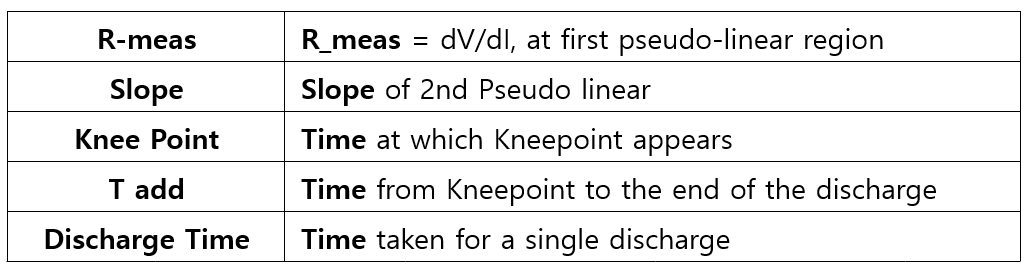

#### **For Feature Reduction/Selection Use**

- monotonicity

#### **For Predict Model**

- linearDegradationModel

***Experiment***** Output**: Health Indicator, Alpha-Lamda Plot

# **2.    Data Exporation & Preprocessing**

### How to Approach Data ?

% ex) B0005.cycle.type(1)
% ex) B0005.cycle(1).data.Voltage_measured

% Case1 : Charge          | Case2 : Discharge       | Case3 : Impedance     |
% ===========================================================================
% Voltage_measured        | Voltage_measured        | Sense_current         |
% Current_measured        | Current_measured        | Battery_current       |
% Temperature_measured    | Temperature_measured    | Current_ratio         |
% Current_charge          | Current_load            | Battery_impedance     |
% Voltage_charge          | Voltage_load            | Rectified_Impedance   |
% Time                    | Time                    | Re                    |
%                         | Capacity                | Rct                   |

## 2.1 Load Data

clear all; close all; clc;

addpath(genpath("Battery_RUL_Prognostic_data"));
addpath(genpath("Functions"));

a1 = dir('Battery_RUL_Prognostic_data/BatteryDataSet_1/*.mat');
a2 = dir('Battery_RUL_Prognostic_data/BatteryDataSet_2/*.mat');
a3 = dir('Battery_RUL_Prognostic_data/BatteryDataSet_3/*.mat');
a4 = dir('Battery_RUL_Prognostic_data/BatteryDataSet_4/*.mat');
a5 = dir('Battery_RUL_Prognostic_data/BatteryDataSet_5/*.mat');
a6 = dir('Battery_RUL_Prognostic_data/BatteryDataSet_6/*.mat');

a0 = [a1; a2; a3; a4; a5; a6];
b = length(a0);
for i = 1:b
    load(sprintf("%s",a0(i).name))
end

## 2.2 **Data Exporation and Preprocessing**

### Set the discharge data index to be imported

By referring to the academic paper we chose, discharge data of the same cycle as the paper were designated.

data_idx = [2,46,126,202,278,356,433,509,588];

### Before Pre-Processing & After Pre-Processing

After the discharge was completed, the part that goes up again were deleted.

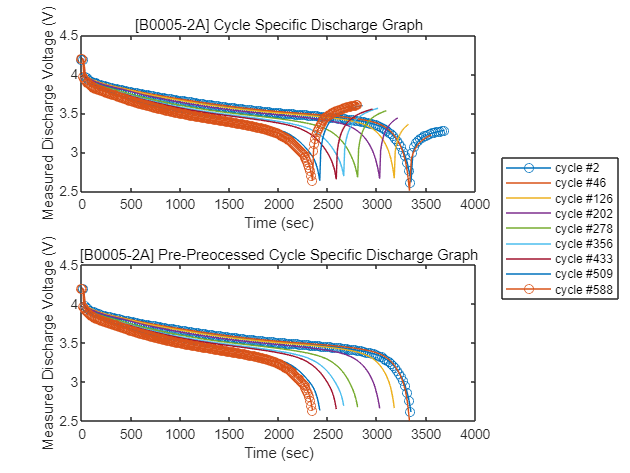

Plt_Compare_Origin_Processed_Discharge(B0005, 2.7, data_idx, '[B0005-2A]')

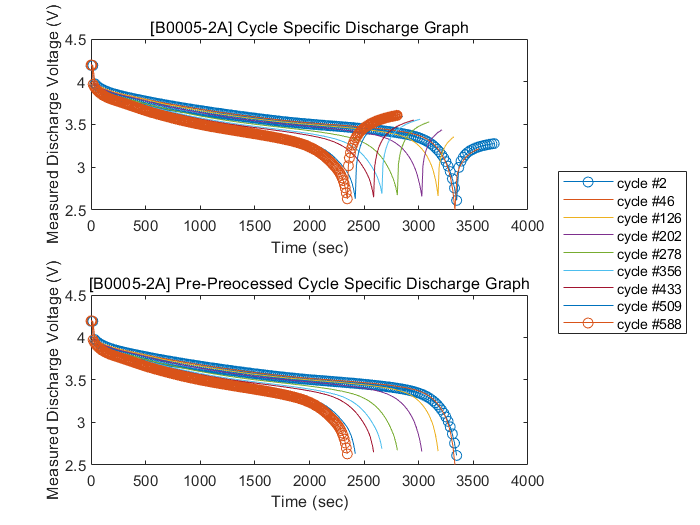

Plt_Compare_Origin_Processed_Discharge(B0005, 2.7, data_idx, '[B0005-2A]')

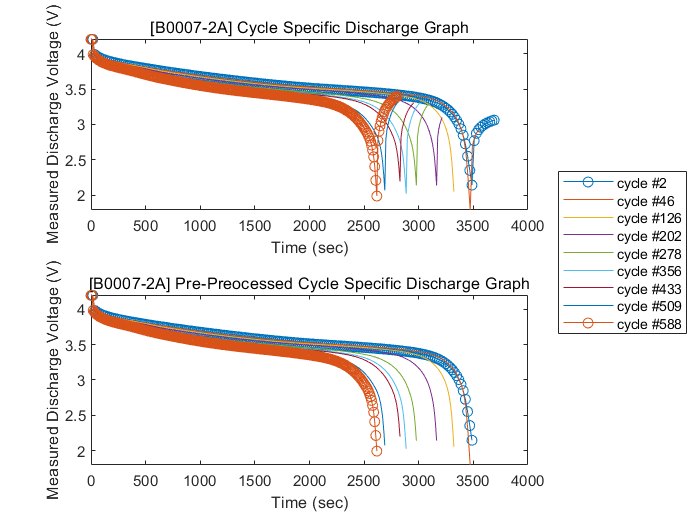

Plt_Compare_Origin_Processed_Discharge(B0007, 2.2, data_idx, '[B0007-2A]')   % For B0005 Dataset

### **Plot Current Curve**

The part confirms that the given data had been discharged with different currents each other.

Some discharge data were discharged at a constant current and some discharge data were discharged at an alternating current.

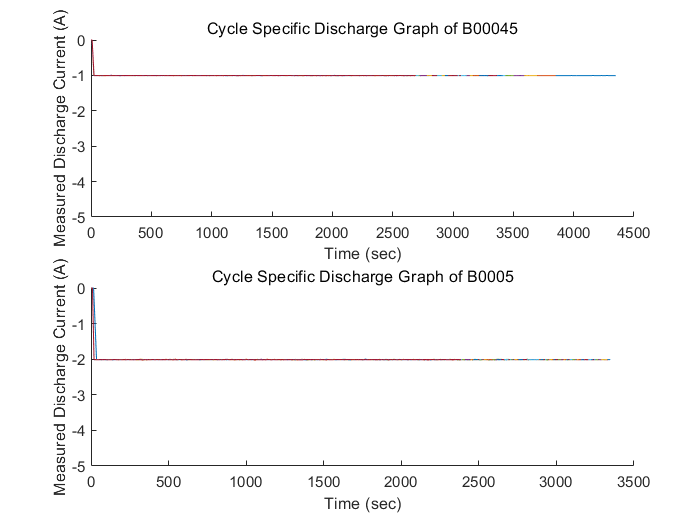

figure()
subplot(211)
Plt_Processed_Current('B00045', B0045, 2)    % B0045 Dataset was discharged to 1A
subplot(212)
Plt_Processed_Current('B0005', B0005, 2.7)   % B0005 Dataset was discharged to 2A

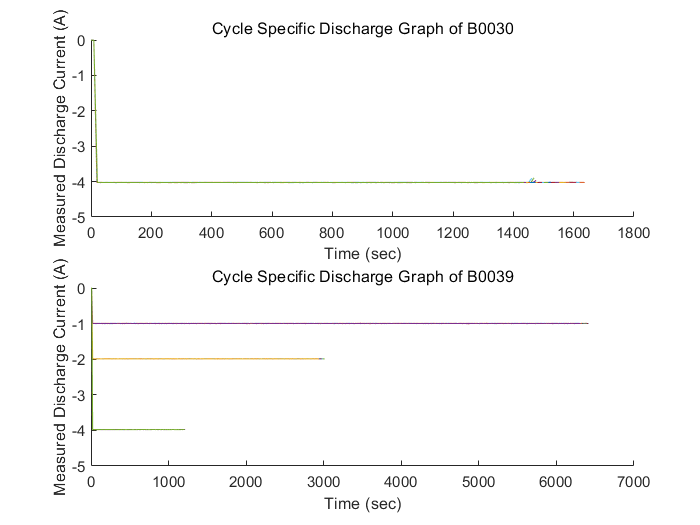

figure()
subplot(211)
Plt_Processed_Current('B0030', B0030, 2.2)   % B0005 Dataset was discharged to 4A
subplot(212)
Plt_Processed_Current('B0039', B0039, 2.7)   % B0039 Dataset was discharged to 1A and 2A

### Plot Discharge Voltage Profile according to each of Discharge Current

When discharged with a larger current, it was confirmed that the discharge was faster.

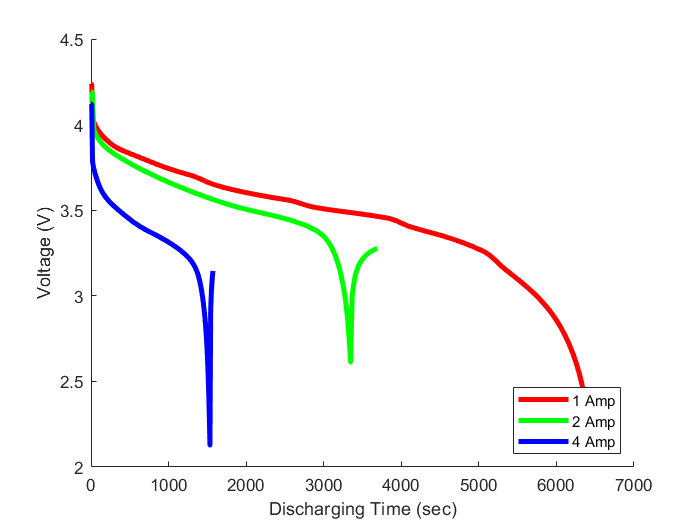

figure

hold on;
plot(B0046.cycle(1).data.Time, B0046.cycle(1).data.Voltage_measured, 'r', 'LineWidth',3);  % 1A Discharge
plot(B0005.cycle(2).data.Time, B0005.cycle(2).data.Voltage_measured, 'g', 'LineWidth',3);  % 2A Discharge
plot(B0030.cycle(2).data.Time, B0030.cycle(2).data.Voltage_measured, 'b', 'LineWidth',3);  % 4A Discharge
hold off;

legend({'1 Amp','2 Amp','4 Amp'},'Location','southeast','NumColumns',1)
ylabel('Voltage (V)');
xlabel('Discharging Time (sec)');

It was confirmed that, in some cases, a 0.05 Hz square wave loading profile with an amplitude of 4A and a 50% Duty Cycle was used for the discharge.

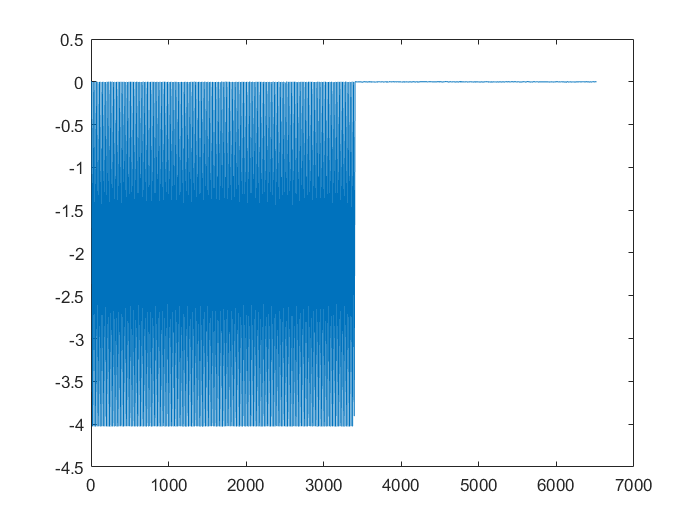

figure
plot(B0025.cycle(4).data.Time, B0025.cycle(4).data.Current_measured);

# **3. Feature Extraction**

#### 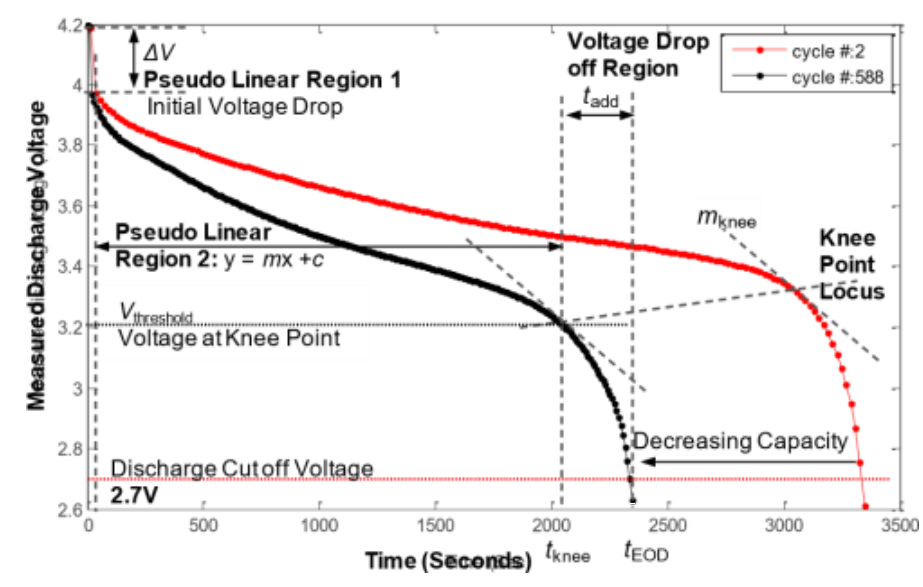

#### 

## **3.1 Feature Extraction**

#### **Feature[1] : Rmeas Feature**

[Feature_Rmeas] = getFeature_Rmeas(B0005)

Feature_Rmeas =     0.1073
    0.1041
    0.1029
    0.1025
    0.1018
    0.1016
    0.1008
    0.1004
    0.0998
    0.1004


#### **Feature[2, 3, 4] : Second Psuedo Linear Slope Feature, KneePoint Feature, T_add Feature**

[Feature_Slope, Feature_Kneepoint, Feature_Tadd] = getFeature_Slope_Kneepoint_Tadd(B0005, 2.7)

Feature_Slope = 	1.0e+-3 *

   -0.1665
   -0.1626
   -0.1573
   -0.1624
   -0.1674
   -0.1675
   -0.1732
   -0.1642
   -0.1704
   -0.1715


Feature_Kneepoint = 	1.0e+03 *

    3.0534
    3.0351
    2.9963
    3.0162
    3.0339
    3.0349
    3.0537
    3.0176
    3.0355
    3.0353


Feature_Tadd =   293.5620
  293.7340
  313.1250
  293.5310
  273.8130
  274.3120
  254.7350
  273.8900
  254.4380
  254.8750


2nd Pseudo Linear Region and Knee Point of B0005 Dataset were displayed, which discharged with a constant current of 2A .

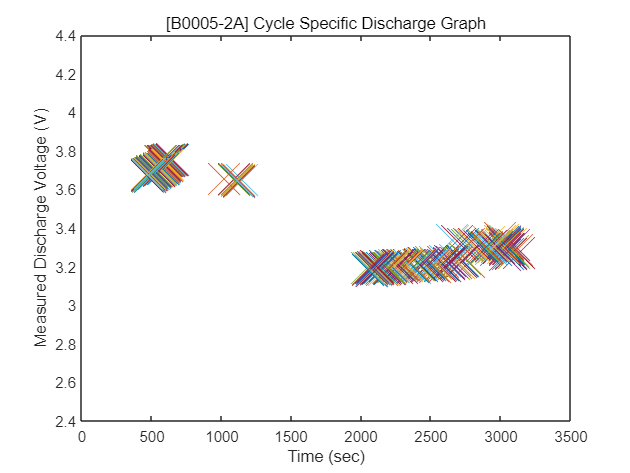

Feature_Plot_CurvePoint(B0005, 2.7, '[B0005-2A]') 

#### **Feature[5] : Time spent on voltage discharge for each cycle of data**

[Feature_Time_discharge] = getFeature_DischargeTime(B0005)'

Feature_Time_discharge = 	1.0e+03 *

    3.6902
    3.6723
    3.6516
    3.6316
    3.6292
    3.6523
    3.6508
    3.5725
    3.5506
    3.5513


## **3.2 Get Feature Table**

[DischargeDateTimes] = getDischargeDateTimes(B0005);   % Pre-preparing for timetable construction: extracting the date of the discharge

column_Name  = [ "R meas" ; "Slope" ; "KneePoint" ; "T add" ; "Discharge TIme"];
column_Name  = '[B0005-2A] ' + string(column_Name);

Discharge_Feature_B0005        = [Feature_Rmeas, Feature_Slope, Feature_Kneepoint, Feature_Tadd, Feature_Time_discharge];
Discharge_Feature_B0005_Table  = array2table(Discharge_Feature_B0005, "VariableNames",column_Name);
featureTable                   = table2timetable(Discharge_Feature_B0005_Table, 'RowTimes', DischargeDateTimes)

featureTable = 168×5 timetable
           Time            [B0005-2A] R meas    [B0005-2A] Slope    [B0005-2A] KneePoint    [B0005-2A] T add    [B0005-2A] Discharge TIme
    ___________________    _________________    ________________    ____________________    ________________    _________________________

    2008-04-02 15:25:41         0.10735           -0.00016654              3053.4                293.56                  3690.2          
    2008-04-02 19:43:48         0.10415           -0.00016263              3035.1                293.73                  3672.3          
    2008-04-03 00:01:06          0.1029           -0.00015734              2996.3                313.12                  3651.6          
    2008-04-03 04:16:37         0.10246           -0.00016236              3016.2                293.53                  3631.6          
    2008-04-03 08:33:25         0.10177           -0.00016743              3033.9                273.81                  3629.2          
  

[thresh_cycle] = getThreshCycle(B0005)

thresh_cycle = 147

featureTable = featureTable(1 : thresh_cycle, :)

featureTable = 147×5 timetable
           Time            [B0005-2A] R meas    [B0005-2A] Slope    [B0005-2A] KneePoint    [B0005-2A] T add    [B0005-2A] Discharge TIme
    ___________________    _________________    ________________    ____________________    ________________    _________________________

    2008-04-02 15:25:41         0.10735           -0.00016654              3053.4                293.56                  3690.2          
    2008-04-02 19:43:48         0.10415           -0.00016263              3035.1                293.73                  3672.3          
    2008-04-03 00:01:06          0.1029           -0.00015734              2996.3                313.12                  3651.6          
    2008-04-03 04:16:37         0.10246           -0.00016236              3016.2                293.53                  3631.6          
    2008-04-03 08:33:25         0.10177           -0.00016743              3033.9                273.81                  3629.2          
  

# 4.    **Post-processing & Feature Selection with Monotonicity**

## 4.1 Feature Post-processing

Extracted features are usually associated with noise. The noise with opposite trend can sometimes be harmful to the RUL prediction. In addition, one of the feature performance metrics, monotonicity, to be introduced next is not robust to noise. Therefore, a causal moving mean filter with a lag window of 5 steps is applied to the extracted features, where "causal" means no future value is used in the moving mean filtering.

% Discharge_Feature_B0005_Table - 168 Cycles -> 147 Cycles
variableNames = featureTable.Properties.VariableNames;
featureTableSmooth = varfun(@(x) movmean(x, [5 0]), featureTable);         %smoothing
featureTableSmooth.Properties.VariableNames = variableNames;

## 4.2 Designate Training Data

In practice, the data of the whole life cycle is not available when developing the prognostic algorithm, but it is reasonable to assume that some data in the early stage of the life cycle has been collected. Hence data collected in the first 101 cycles (70% of the life cycle) is treated as training data. The following feature importance ranking and fusion is only based on the training data.

breaktime   = DischargeDateTimes(floor(height(featureTable) * 0.7));
breakpoint  = find(featureTable.Time < breaktime , 1, 'last');

trainData   = featureTable(1:breakpoint, :);

## 4.3 Monotonicity

Feature Importance Ranking through Monotonicity

Monotonicity of $i$th feature $x_i$ is computed as


$$\textrm{Monotonicity}\left(x_i \right)=\frac{1}{m}\sum_{j=1}^m \frac{\left|\textrm{number}\;\textrm{of}\;\textrm{positive}\;\textrm{diff}\left(x_i^j \right)\;-\;\textrm{number}\;\textrm{of}\;\textrm{negative}\;\textrm{diff}\left(x_i^j \right)\right|}{n-1}$$


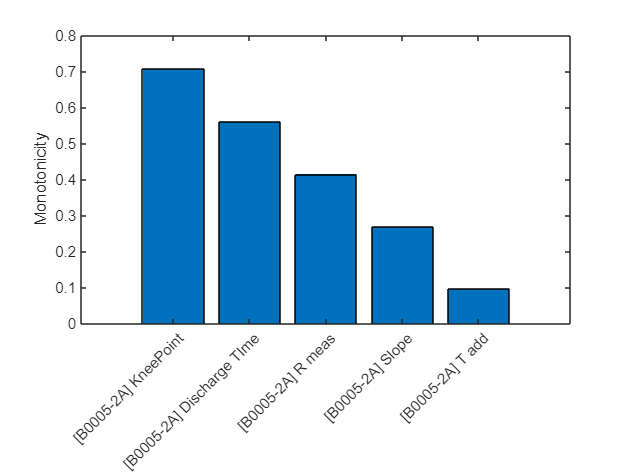

% Since moving window smoothing is already done, set 'WindowSize' to 0 to
% turn off the smoothing within the function
featureImportance = monotonicity(featureTable( floor(breakpoint*0.6) : breakpoint, : ), 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity');

According to the monotonicity value, a significant feature for machine learning may be selected.

## 4.4 Feature Selection

Features with feature importance score larger than 0.5 are selected for feature fusion in the next section.

trainDataSelected  = trainData(:, featureImportance{:,:} > 0.5);
featureSelected    = featureTableSmooth(:, featureImportance{:,:} > 0.5)

featureSelected = 147×2 timetable
           Time            [B0005-2A] KneePoint    [B0005-2A] Discharge TIme
    ___________________    ____________________    _________________________

    2008-04-02 15:25:41           3053.4                    3690.2          
    2008-04-02 19:43:48           3044.2                    3681.3          
    2008-04-03 00:01:06           3028.3                    3671.4          
    2008-04-03 04:16:37           3025.2                    3661.4          
    2008-04-03 08:33:25             3027                      3655          
    2008-04-03 12:55:10           3028.3                    3654.5          
    2008-04-03 17:17:16           3028.3                      3648          
    2008-04-03 21:28:14           3025.4                    3631.3          
    2008-04-04 01:38:15             3032                    3614.5          
    2008-04-04 05:48:08           3035.1                    3601.1          
    2008-04-04 09:57:19           3038.8 

# **5.    Dimention Reduction with PCA**

Principal Component Analysis (PCA) is used for dimension reduction and feature fusion.

Before performing PCA, it is a good practice to normalize the features into the same scale. 

## 5.1 Normalize Train Data

Note that PCA coefficients and the mean and standard deviation used in normalization are obtained from training data, and applied to the entire dataset.

meanTrain            = mean(trainDataSelected{:,:});
sdTrain              = std(trainDataSelected{:,:});
trainDataNormalized  = (trainDataSelected{:,:} - meanTrain)./sdTrain;
coef                 = pca(trainDataNormalized);

The mean, standard deviation and PCA coefficients are used to process the entire data set.

PCA1  = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
PCA2  = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

Visualize the data in the space of the first two principal components.

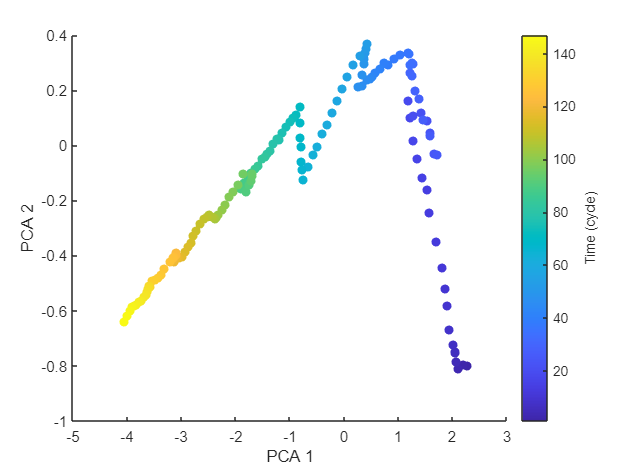

figure
timeUnit = 'cycle';

numData = size(featureTable, 1);
scatter(PCA1, PCA2, [], 1:numData, 'filled')
xlabel('PCA 1');   ylabel('PCA 2')
cbar = colorbar;
ylabel(cbar, ['Time (' timeUnit ')'])

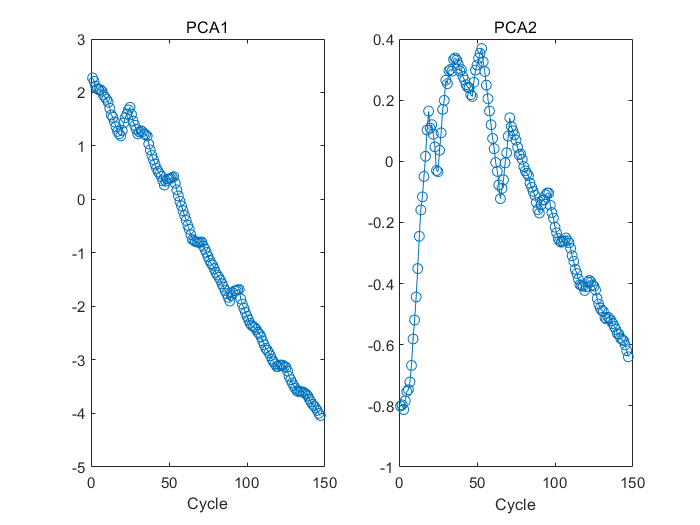

figure
subplot(1,2,1); plot(PCA1, '-o'); xlabel('Cycle'); subtitle('PCA1');
subplot(1,2,2); plot(PCA2, '-o'); xlabel('Cycle'); subtitle('PCA2');

## 5.2 Get Health Indicator

The plot indicates that the first principal component is decreasing as the battery approaches to failure. Therefore, the first principal component is a promising fused health indicator.

healthIndicator = PCA1;

Visualize the health indicator.

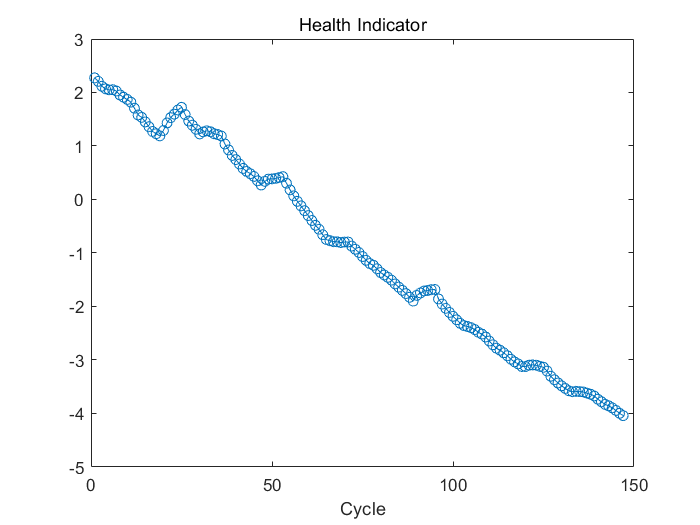

figure
t = 1 : 1 : thresh_cycle;
plot(t, healthIndicator, '-o');   xlabel('Cycle');   title('Health Indicator')

# **6.    RUL**

## 6-1. Fault Monitoring and RUL Estimation 

Here an Exponential Degradation Model is fit to the health indicator extracted in the last section, and the performances is evaluated in the next section.

First shift the health indicator so that it starts from 0.

healthIndicator = healthIndicator - healthIndicator(1);

The selection of threshold is usually based on the historical records of the machine or some domain-specific knowledge. Since no historical data is available in this dataset, the last value of the health indicator is chosen as the threshold. It is recommended to choose the threshold based on the smoothed (historical) data so that the delay effect of smoothing will be partially mitigated.

threshold = healthIndicator(end);

**Linear degradation models** are useful when the monitored signal is a log scale signal or when the component does not experience cumulative degradation.

Therefore, Now create an linear degradation model.

mdl = linearDegradationModel(...
    'Theta', threshold/thresh_cycle, ...
    'ThetaVariance', 1/thresh_cycle, ...
    'Phi', healthIndicator(1), ...
    'NoiseVariance', 0.01);

Use `predictRUL` and `update` methods to predict the RUL and update the parameter distribution in real time.

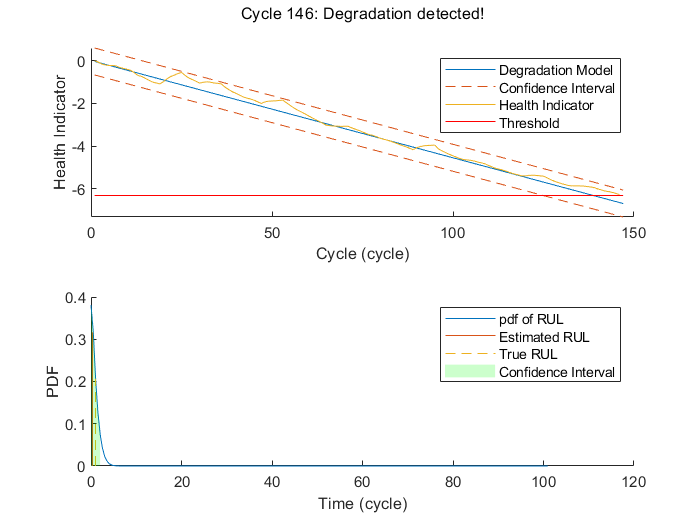

% Keep records at each iteration
totalCycle = length(healthIndicator) - 1;
trueRULs = zeros(totalCycle, 1);
estRULs  = zeros(totalCycle, 1);
CIRULs   = zeros(totalCycle, 2);
pdfRULs  = cell(totalCycle, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentCycle = 1 : totalCycle
    
    % Update model parameter posterior distribution
    update(mdl, [currentCycle healthIndicator(currentCycle)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentCycle healthIndicator(currentCycle)], ...
                                         threshold);

    trueRUL = totalCycle - currentCycle + 1;

    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentCycle, healthIndicator, mdl, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
       
    % Keep prediction results
    estRULs(currentCycle)   = estRUL;
    trueRULs(currentCycle)  = trueRUL;
    CIRULs(currentCycle, :) = CIRUL;
    pdfRULs{currentCycle}   = pdfRUL;

    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

**As the breakdown is imminent, it seems that the specified threshold value has been reached, so it has been properly learned and prediction has been successful.**

## 6-2. Performance Analysis

$\alpha$-$\lambda$ plot is used for prognostic performance analysis [5], where $\alpha \;$bound is set to 20%. The probability that the estimated RUL is between the $\alpha$ bound of the true RUL is calculated as a performance metric of the model:


$$\Pr \left(r^* \left(t\right)-\alpha r^* \left(t\right)<r\left(t\right)<r^* \left(t\right)+\alpha r^* \left(t\right)\left|\Theta \left(t\right)\right.\right)$$


where $r\left(t\right)$ is the estimated RUL at time $t$, $r^* \left(t\right)$ is the true RUL at time $t$, $\Theta \left(t\right)$ is the estimated model parameters at time $t$.

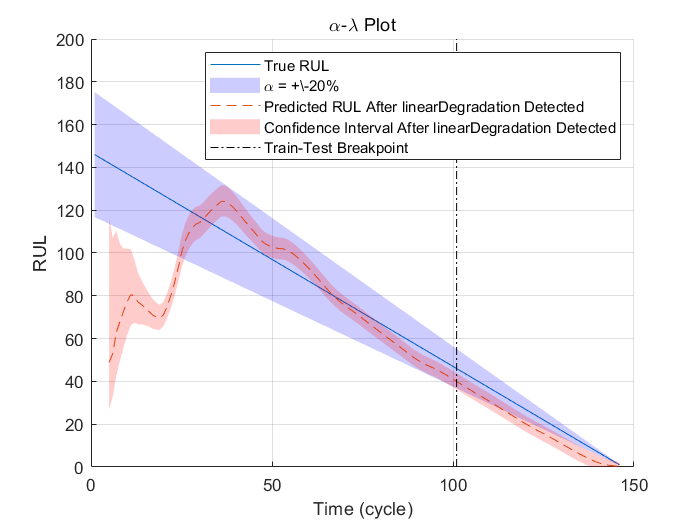

alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;

prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
                             pdfRULs, detectTime, breakpoint, timeUnit);

% trueRULs = actual life expectancy
% estRULs  = Predicted life expectancy
% CIRULs   = Confidence interval

title('\alpha-\lambda Plot')

# **7.    Discussion & Conclusion**

## Discussion

This study was initiated to predict the remaining life of the battery.

The battery dataset of NASA which the battery with the maximum charging voltage of 4.2 V was discharged to 2.7 V, and recharged was selected as the dataset of this study.

As the discharge cycle increases, the discharge capacity decreases, and in this study, we considered that the life of the battery is over when the discharge capacity of the battery drops to less than about 70%. Therefore, we did not use all cycles of a given dataset, but only cycles from the start point to the end of life.

As a result of checking a voltage discharge curve, two pseudo linear intervals were observed, and based on this, feature extraction was performed. Also, it was confirmed that the time required for discharge naturally decreased as the discharge capacity of the battery decreased, and the time required for discharge was selected as a feature.

Monotonicity was confirmed for the extracted feature, and monotonicity values of the four features extracted from the pseudo linear section showed a linear pattern. This seems to be because one feature has a close correlation with the other. Therefore, only one feature was selected in the pseudo linear section and used for model learning.

The Health Indicator was selected through normalization -> PCA, and a linearly decreasing graph, such as y = -x, was found. Thus, the Linear Degradation model was used as the RUL prediction model

70% of the total cycles used for learning were used as training data, and it was observed through the alpha-lambda Plot that the test results almost converge within the error range of 20%.

That is, it was confirmed that the battery life prediction model was successfully constructed in the constant current discharge state.

## Conclusion

Through NASA Battery Dataset, We construct RUL model of the lithium-ion battery with constant current discharge condition.

Accessed by a data-based algorithm, five features were extracted from the discharge voltage curve.

Monotonyity of the extracted feature was checked, and two features were selected and used.

After normalization, HealthIndicator was set through PCA, and the RUL of the battery was predicted successfully using the Linear Degradation model with similar shape.

Through this result of project, the battery may be used more efficiently by predicting the life of the battery and performing repair/replacement before a failure occurs.

However, it is limited to the constant loading scenario, and the algorithm shall be improved to predict the battery RUL in the actual environment (i.e., the variable loading scenario).

# **8.    Reference**

**[1]    **Saxena, A., Celaya, J. R., Roychoudhury, I., Saha, S., Saha, B., & Goebel, K. (2012, January). Designing data-driven battery prognostic approaches for variable loading profiles: Some lessons learned. In *European conference of prognostics and health management society* (pp. 72-732).

**[2]    **Guo, P., Cheng, Z., & Yang, L. (2019). A data-driven remaining capacity estimation approach for lithium-ion batteries based on charging health feature extraction. *Journal of Power Sources*, *412*, 442-450.